Load robot model, set joint angles for home position

clear all;
clc; 
close all;

robot = importrobot("C:\Users\atjensvo\cernbox\Documents\GitHub\MasterThesis\MATLAB\Collision_test.urdf", "DataFormat", "row");

% Set home configuration
q_home = [0 0 0 0 0 0 0 0 0];

showdetails(robot);

--------------------
Robot: (23 bodies)

 Idx                      Body Name         Joint Name         Joint Type                      Parent Name(Idx)   Children Name(s)
 ---                      ---------         ----------         ----------                      ----------------   ----------------
   1                 Wagon_slider_1           Slider 1          prismatic                          base_link(0)   J0_roll_v2_1(2)  
   2                   J0_roll_v2_1         Revolute 2           revolute                     Wagon_slider_1(1)   J1_pitch_v1_1(3)  
   3                  J1_pitch_v1_1         Revolute 3           revolute                       J0_roll_v2_1(2)   J2_prismatic_v2_1(4)  
   4              J2_prismatic_v2_1           Slider 6          prismatic                      J1_pitch_v1_1(3)   80I_v2_1(5)  
   5                       80I_v2_1            Rigid 7              fixed                  J2_prismatic_v2_1(4)   80mm_Connector_v1_1(6)  
   6            80mm_Connect


% Check for collisions in home configuration

% [isColliding, sepDist, witnessPts] = checkCollision(robot, q_home);
% 
% if isColliding
%     disp('The robot is in self-collision in the home configuration.');
% else
%     disp('No self-collision detected in the home configuration.');
% end

Set joint limits and show arm in home position

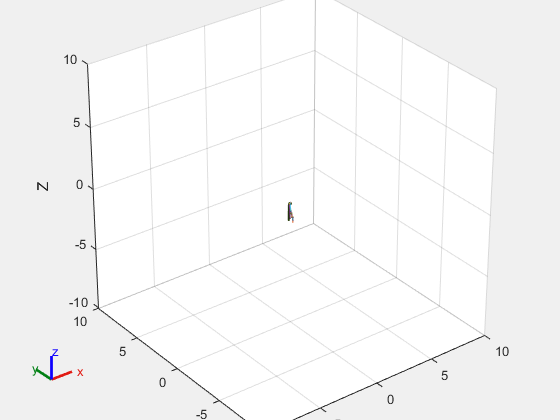

eeName = "Tool_1";
config = q_home;

%gui = interactiveRigidBodyTree(robot,"Configuration",q_home)
figure;
show(robot,q_home, Visuals="off", Collisions="on");
axis equal;          
xlim([-10, 10]);   
ylim([-10, 10]);      
zlim([-10, 10]);   
view(3);   
hold on

Generate environment

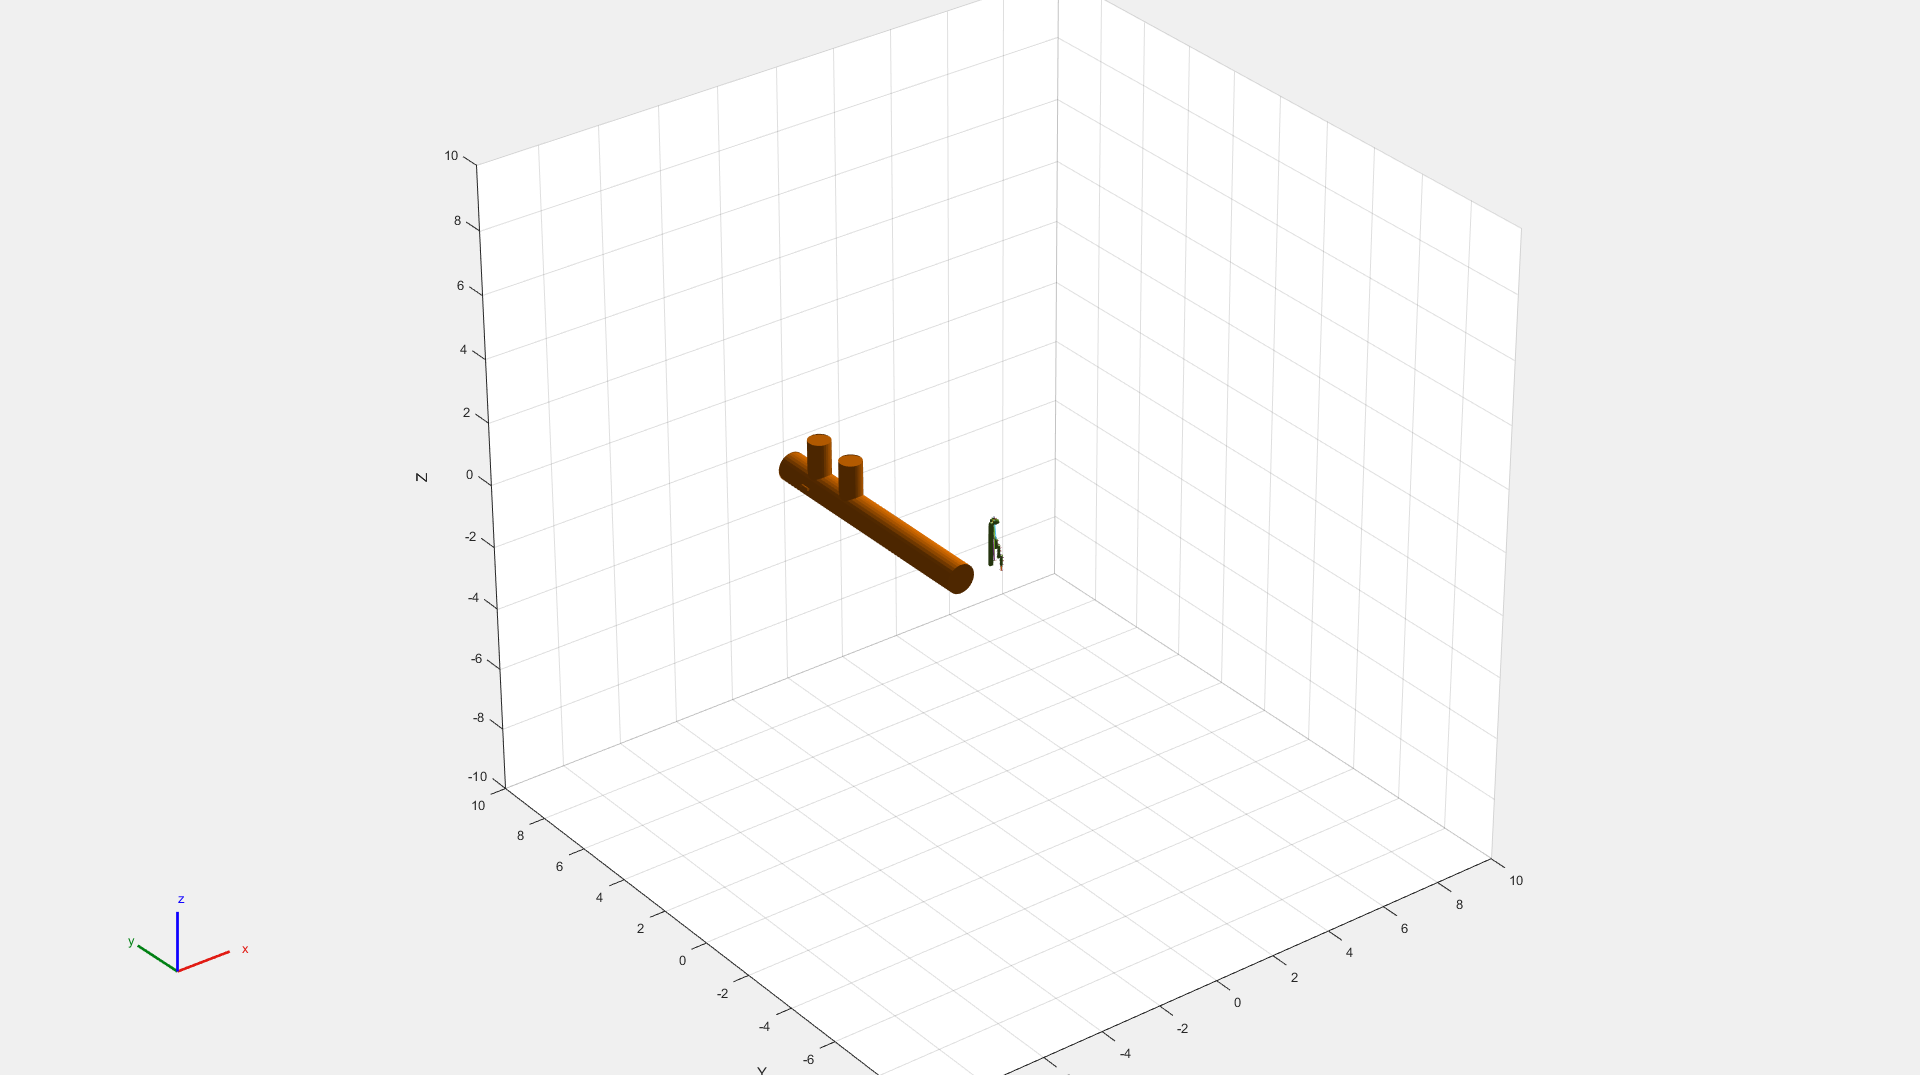

collisionCylinders = {
    collisionCylinder(0.457, 8.0),  % Main Pipe
    collisionCylinder(0.044, 0.3),  % Front BLM
    collisionCylinder(0.044, 0.3),  % Back BLM
    collisionCylinder(0.350, 1.5),  % First Obstacle
    collisionCylinder(0.350, 1.5)   % Second Obstacle
};

cylinderPoses = [
    -0.958, 4.260, -1.707, 1, 0, 0, pi/2; 
    -0.458, 2.015, -1.627, 1, 0, 0, pi/2;
    -1.456, 6.921, -1.627, 1, 0, 0, pi/2; 
    -0.952, 5.400, -0.986, 1, 0, 0, 0;
    -0.952, 6.900, -0.986, 1, 0, 0, 0
];

for i = 1:length(collisionCylinders)
    P = trvec2tform(cylinderPoses(i, 1:3));
    R = axang2tform(cylinderPoses(i, 4:7));
    collisionCylinders{i}.Pose = P * R;
    show(collisionCylinders{i});
end

Define goal poses

goalPoses = [
          -0.000, 0.000, -2.000, 1, 0, 0, 0;  % Start
          % -0.476, 2.015, -1.400, 1, 0, 0, 0;  % Front BLM
          % -0.476, 6.200, -1.400, 1, 0, 0, 0;  % Front Obstacles
          % -0.476, 6.200, -1.000, 0, 1, 0, pi/4;  % Front Obstacles
          % %-0.800, 6.400, -1.000, 0, 1, 0, pi/4;  % Between Obstacles
          % -1.100, 6.400, -1.000, 0, 1, 0, pi/2;  % Back Obstacles
          % -1.469, 6.200, -1.300, 1, 0, 0, 0;  % Back Obstacles
          % %-1.469, 6.200, -1.400, 1, 0, 0, pi/4;  % Back Obstacles
          % -1.469, 6.400, -1.400, 1, 0, 0, 0;  % Back Obstacles
          % -1.469, 6.500, -1.400, 1, 0, 0, pi/8;  % Back Obstacles
          % -1.469, 6.921, -1.400, 1, 0, 0, pi/6;  % Back BLM
            ];

disp('Plotting all target poses...');

Plotting all target poses...


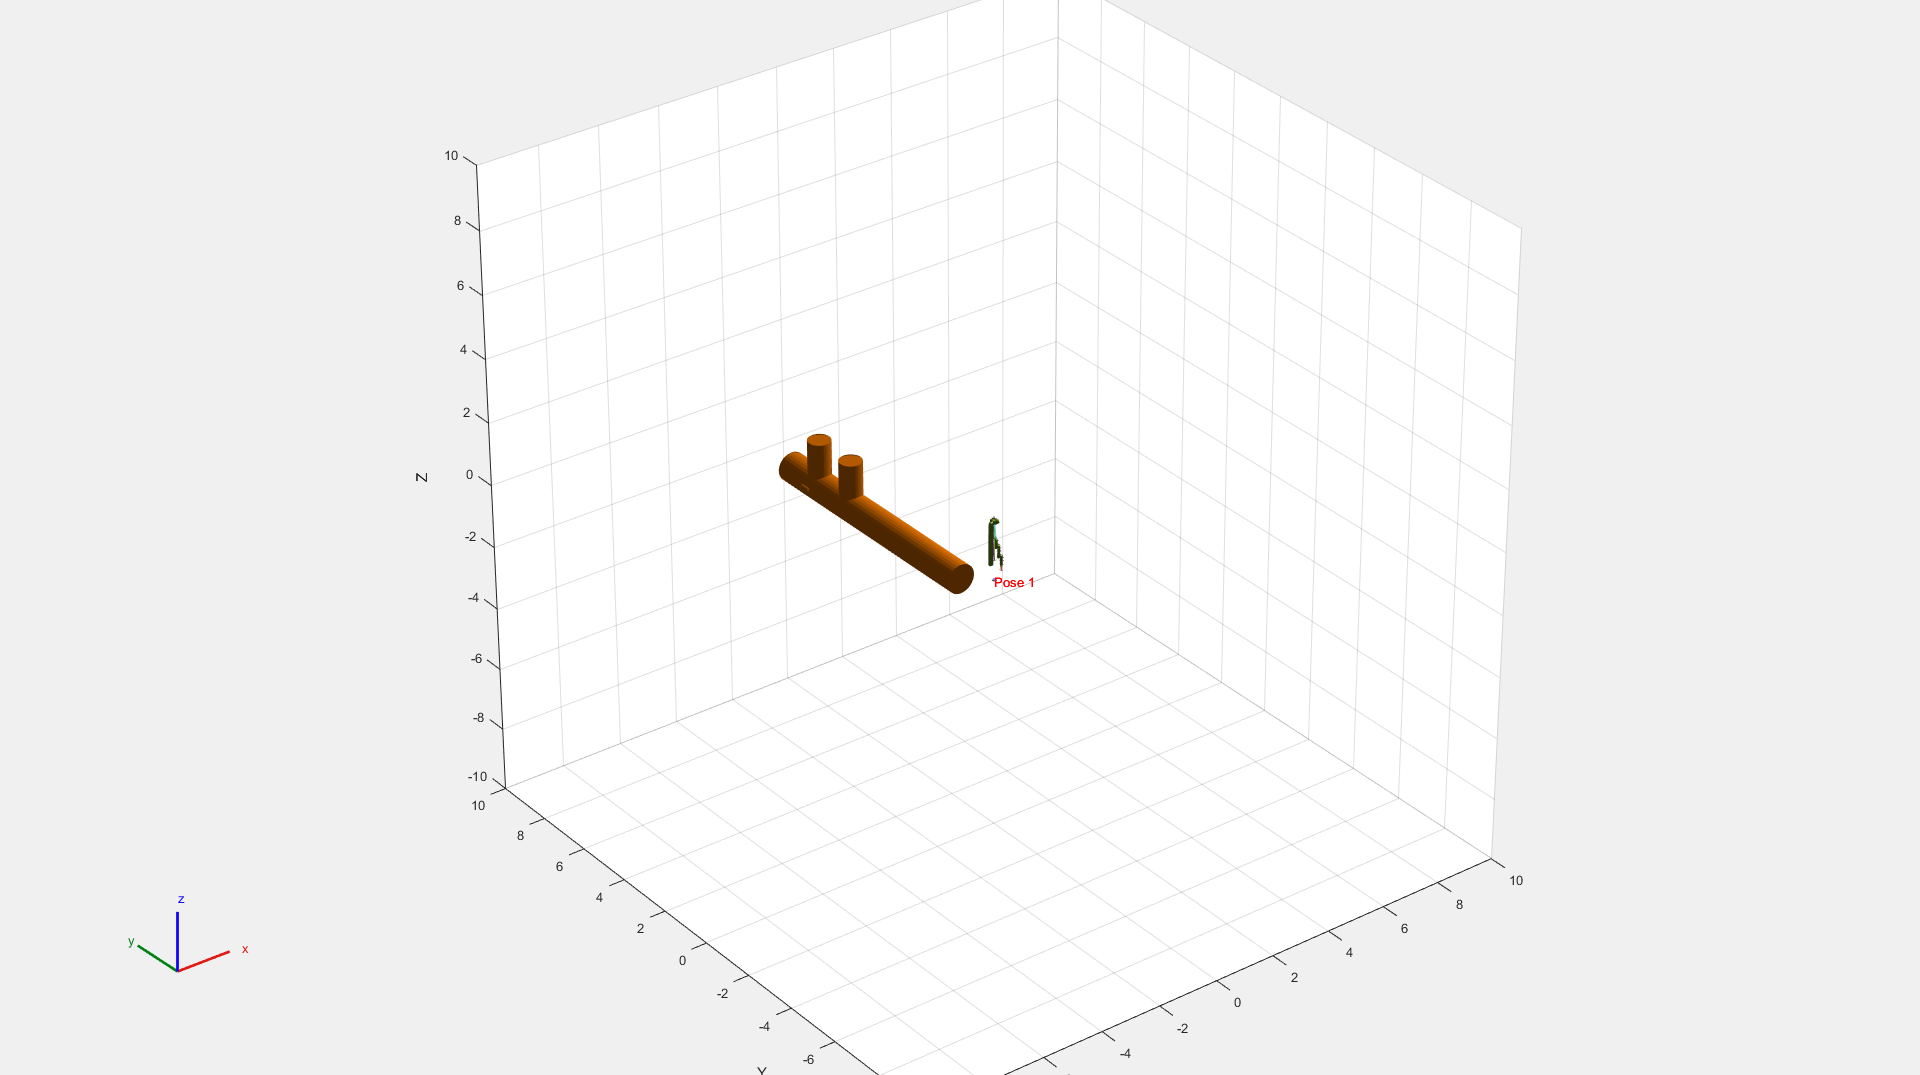

for i = 1:size(goalPoses, 1)
    pos = goalPoses(i, 1:3);
    rot = goalPoses(i, 4:7);
    poseTF = trvec2tform(pos) * axang2tform(rot);
    
    plotTransforms(pos, tform2quat(poseTF), "FrameSize", 0.1);
    text(pos(1), pos(2), pos(3), sprintf('Pose %d', i), 'FontSize', 10, 'Color', 'r');
end

Create RRT trajectory planner

planner = manipulatorRRT(robot,collisionCylinders);
planner.SkippedSelfCollisions = 'parent';
planner.EnableConnectHeuristic = true

planner =   manipulatorRRT with properties:

      MaxConnectionDistance: 0.1000
              MaxIterations: 10000
     EnableConnectHeuristic: 1
         ValidationDistance: 0.0100
    WorkspaceGoalRegionBias: 0.5000
        IgnoreSelfCollision: 0
      SkippedSelfCollisions: 'parent'


planner.MaxConnectionDistance = 0.1;
planner.ValidationDistance = 0.01;
planner.MaxIterations = 100;
rng(0)

Create IK solver

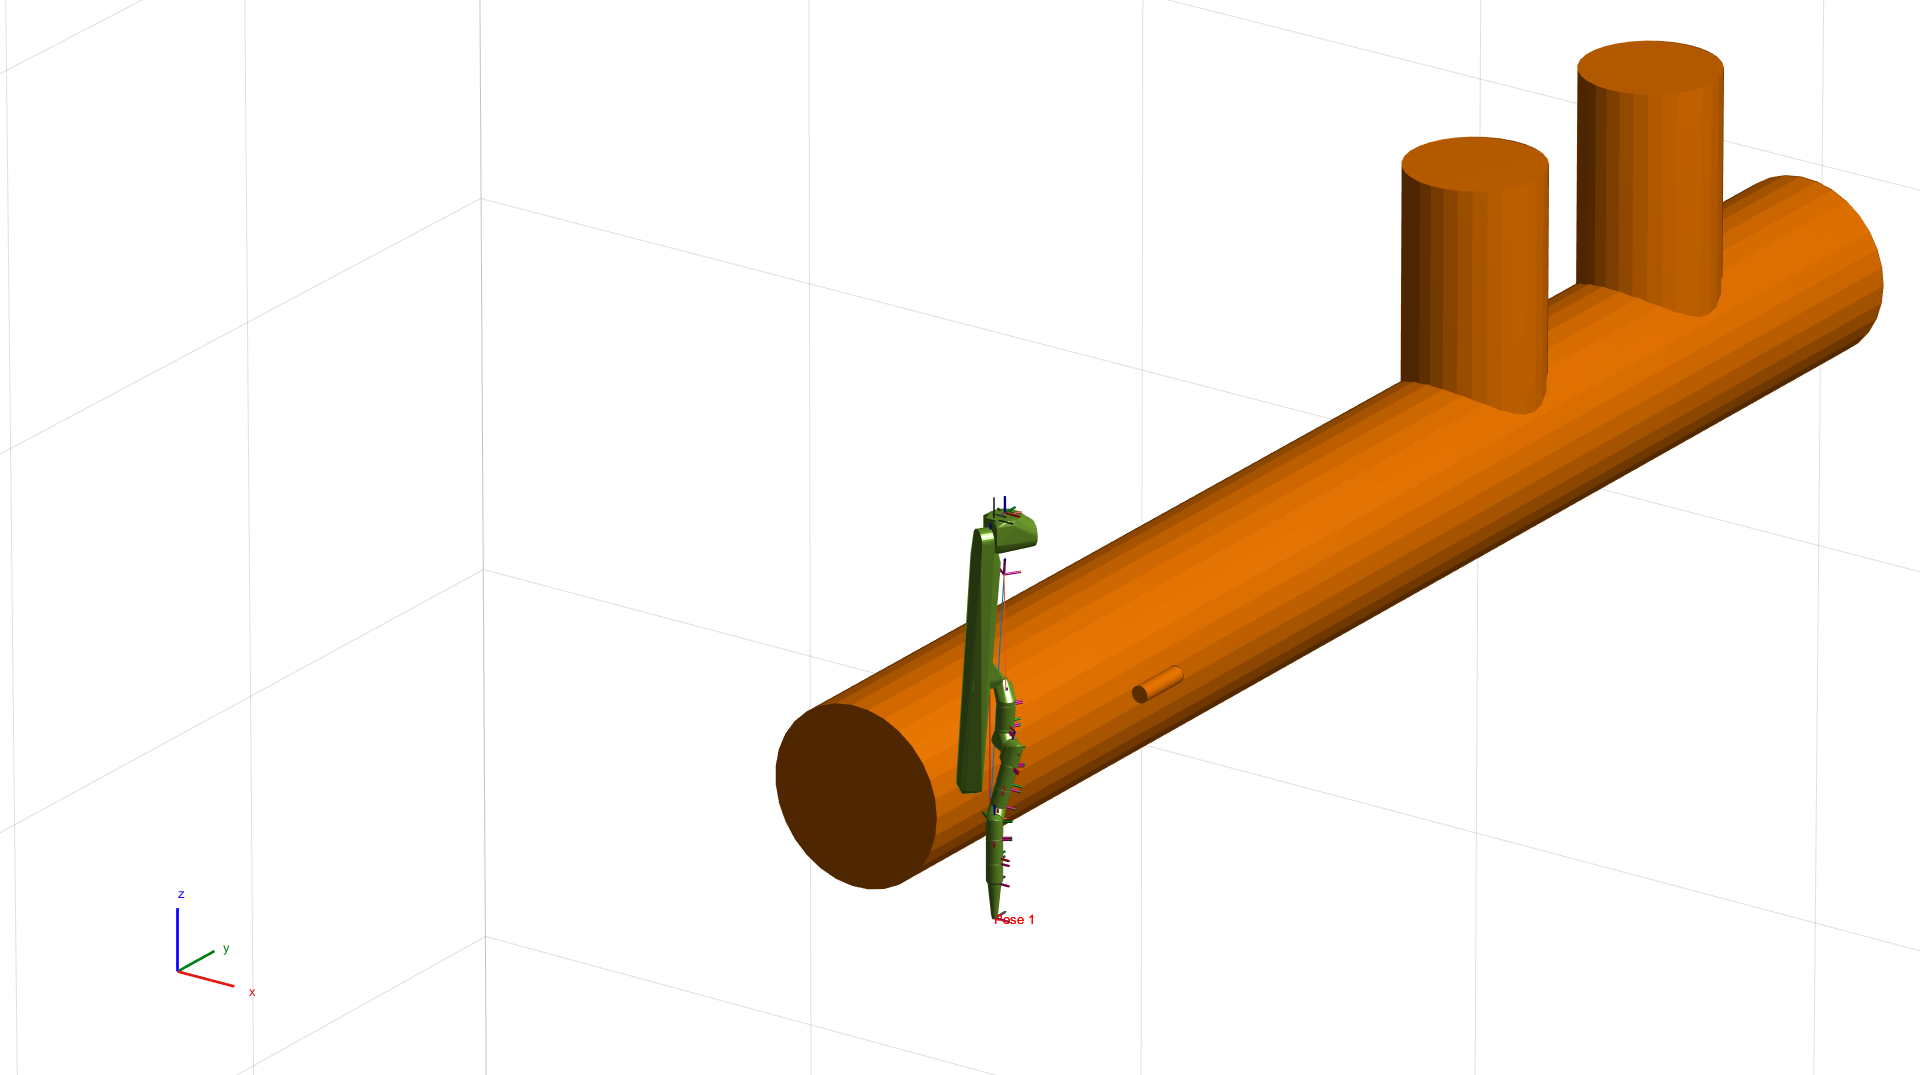

pose reached. Press any key to move to next.


gik = generalizedInverseKinematics('RigidBodyTree', robot, 'ConstraintInputs',{'position', 'orientation'});
% Orientation_Constraint = constraintOrientationTarget(eeName);
% Orientation_Constraint.OrientationTolerance = pi/4;
% Position_Constraint = constraintPositionTarget(eeName);
% Position_Constraint.PositionTolerance = 0.05;
% Position_Constraint.Weights = 1;
% Orientation_Constraint.Weights = 0;

currentConfig = config;  % Start with home position

% Define Pose goals
pos_goal = constraintPositionTarget(eeName);
ori_goal = constraintOrientationTarget(eeName);

% Loop through goal poses
for i = 1:size(goalPoses, 1)
    position = goalPoses(i, 1:3);
    orientation = goalPoses(i, 4:7);

    % Convert to transformation matrix
    goalPose = trvec2tform(position) * quat2tform(orientation);

   % Set constraints
    pos_goal.TargetPosition = position;
    ori_goal.TargetOrientation = orientation; 

    % Solve IK 
    [goalConfig, solInfo] = gik(currentConfig, pos_goal, ori_goal);

    % Check if IK solution is valid
    if solInfo.Status ~= "success"
        warning("IK solution failed for goal %d. Skipping.", i);
        continue;
    end

    % Check for collision
    if checkCollision(robot, goalConfig, collisionCylinders)
        warning("Goal %d is too close to obstacles. Skipping.", i);
        continue;
    end

    % Plan and execute path
    rng('default');
    path = plan(planner, currentConfig, goalConfig);
    if isempty(path)
        warning("No valid path found for goal %d. Skipping.", i);
        continue;
    end

    interpStates = interpolate(planner, path);
    for j = 1:2:size(interpStates, 1)
        show(robot, interpStates(j, :), "PreservePlot", false, "Visuals", "off", "Collisions", "on");
        title(sprintf("Moving to Goal %d", i))
        drawnow;
    end

    % Update current config
    currentConfig = goalConfig;
    disp('pose reached. Press any key to move to next.');
    pause('on');
    pause;
end